# Práctica 6

*Alumna: Navil Pineda Rugerio.*

*No. de lista: 19.*

*Ingeniería en Inteligencia Artificial.*

*5to Semestre.*

### Ejercicio 1.

Señales.

x1 = [1,-1];
x2 = [1,1,-1,-1];
x3 = [3,-1,4,2];
x4 = [1,0,0,-1,0,0];

Graficar señales.

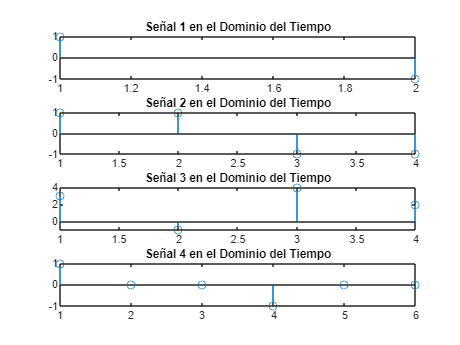

subplot(4,1,1)
stem(x1)
title("Señal " + num2str(1) + " en el Dominio del Tiempo")

subplot(4,1,2)
stem(x2)
title("Señal " + num2str(2) + " en el Dominio del Tiempo")

subplot(4,1,3)
stem(x3)
title("Señal " + num2str(3) + " en el Dominio del Tiempo")

subplot(4,1,4)
stem(x4)
title("Señal " + num2str(4) + " en el Dominio del Tiempo")

Calcular la transformada.

% SEÑAL 1---------------------------------------------------------------
y1 = fft(x1);
m1 = abs(y1); % Magnitud
y1(m1<1e-6) = 0;
p1 = unwrap(angle(y1)); % Fase
f1 = (0:length(y1)-1)*100/length(y1);

% SEÑAL 2---------------------------------------------------------------
y2 = fft(x2);
m2 = abs(y2); % Magnitud
y2(m2<1e-6) = 0;
p2 = unwrap(angle(y2)); % Fase
f2 = (0:length(y2)-1)*100/length(y2);

% SEÑAL 3---------------------------------------------------------------
y3 = fft(x3);
m3 = abs(y3); % Magnitud
y3(m3<1e-6) = 0;
p3 = unwrap(angle(y3)); % Fase
f3 = (0:length(y3)-1)*100/length(y3);

% SEÑAL 4---------------------------------------------------------------
y4 = fft(x4);
m4 = abs(y4); % Magnitud
y4(m4<1e-6) = 0;
p4 = unwrap(angle(y4)); % Fase
f4 = (0:length(y4)-1)*100/length(y4);

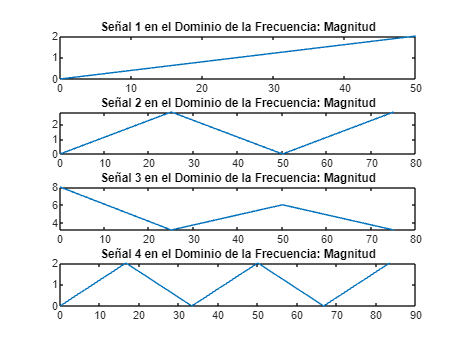

% SEÑAL 1---------------------------------------------------------------
subplot(4,1,1)
plot(f1,m1)
title("Señal " + num2str(1) + " en el Dominio de la Frecuencia: Magnitud")

% SEÑAL 2---------------------------------------------------------------
subplot(4,1,2)
plot(f2,m2)
title("Señal " + num2str(2) + " en el Dominio de la Frecuencia: Magnitud")

% SEÑAL 3---------------------------------------------------------------
subplot(4,1,3)
plot(f3,m3)
title("Señal " + num2str(3) + " en el Dominio de la Frecuencia: Magnitud")

% SEÑAL 4---------------------------------------------------------------
subplot(4,1,4)
plot(f4,m4)
title("Señal " + num2str(4) + " en el Dominio de la Frecuencia: Magnitud")

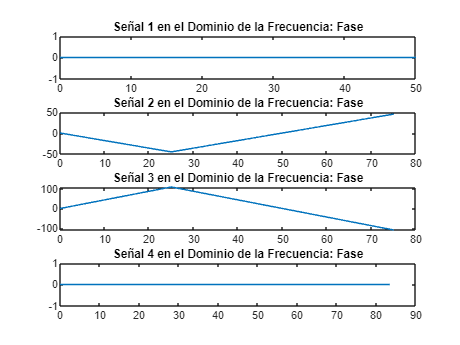

% SEÑAL 1---------------------------------------------------------------
subplot(4,1,1)
plot(f1,p1*180/pi)
title("Señal " + num2str(1) + " en el Dominio de la Frecuencia: Fase")

% SEÑAL 2---------------------------------------------------------------
subplot(4,1,2)
plot(f2,p2*180/pi)
title("Señal " + num2str(2) + " en el Dominio de la Frecuencia: Fase")

% SEÑAL 3---------------------------------------------------------------
subplot(4,1,3)
plot(f3,p3*180/pi)
title("Señal " + num2str(3) + " en el Dominio de la Frecuencia: Fase")

% SEÑAL 4---------------------------------------------------------------
subplot(4,1,4)
plot(f4,p4*180/pi)
title("Señal " + num2str(4) + " en el Dominio de la Frecuencia: Fase")

### Ejercicio 2.

% Vector de tiempo
t = [0,1,2,3];

Señal.

x5 = cos(pi*t);

Graficarla.

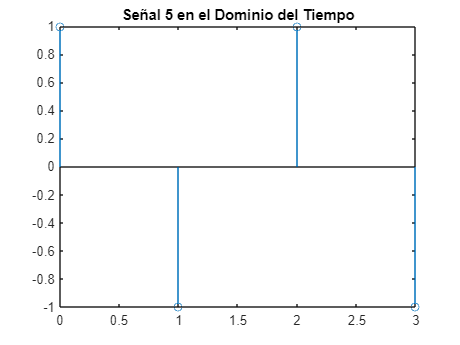

subplot(1,1,1)
stem(t,x5)
title("Señal " + num2str(5) + " en el Dominio del Tiempo")

Calcular su transformada.

y5 = fft(x5);

m5 = abs(y5); % Magnitud
y5(m5<1e-6) = 0;
p5 = unwrap(angle(y5)); % Fase
f5 = (0:length(y5)-1)*100/length(y5);

Graficar su transformada.

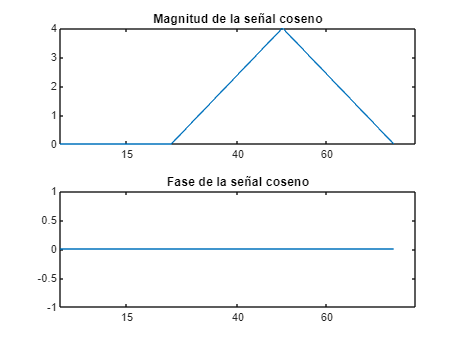

subplot(2,1,1)
plot(f5,m5)
title('Magnitud de la señal coseno')
ax = gca;
ax.XTick = [15 40 60 85];

subplot(2,1,2)
plot(f5,p5*180/pi)
title('Fase de la señal coseno')
ax = gca;
ax.XTick = [15 40 60 85];

### Ejercicio 3.

Señales.

Y1=[0,2];
Y2=[0,-2j,0,2j];
Y3=[0,4,0,0,4];

X1 = ifft(Y1);
X2 = ifft(Y2);
X3 = ifft(Y3);

fprintf('IFFT de señal 1');

IFFT de señal 1

disp(X1);

     1    -1



fprintf('IFFT de señal 2');

IFFT de señal 2

disp(X2);

     0     1     0    -1



fprintf('IFFT de señal 3');

IFFT de señal 3

disp(X3);

    1.6000    0.4944   -1.2944   -1.2944    0.4944



### Ejercicio 4.

% Señal
F = @(t) sin(2*pi*5*t);

% Periodo de muestreo
T = 0.01;

% Número de muestras
N = 100;

% Vector de frecuencias en los que se muestreará la DTFT
W = linspace(-pi, pi, N);

% Llamar a la funcion
[F_dft, M, P, frec] = DTFT(F, T, N, W);
fprintf('Función de DTFT');

Función de DTFT

disp(F_dft);

  -0.1584 + 0.0090i  -0.1584 + 0.0089i  -0.1584 + 0.0087i  -0.1584 + 0.0086i  -0.1584 + 0.0084i  -0.1584 + 0.0082i  -0.1584 + 0.0081i  -0.1584 + 0.0079i  -0.1584 + 0.0078i  -0.1584 + 0.0076i  -0.1584 + 0.0074i  -0.1584 + 0.0073i  -0.1584 + 0.0071i  -0.1584 + 0.0070i  -0.1584 + 0.0068i  -0.1584 + 0.0067i  -0.1584 + 0.0065i  -0.1584 + 0.0063i  -0.1584 + 0.0062i  -0.1584 + 0.0060i  -0.1584 + 0.0059i  -0.1584 + 0.0057i  -0.1584 + 0.0056i  -0.1584 + 0.0054i  -0.1584 + 0.0052i  -0.1584 + 0.0051i  -0.1584 + 0.0049i  -0.1584 + 0.0048i  -0.1584 + 0.0046i  -0.1584 + 0.0045i  -0.1584 + 0.0043i  -0.1584 + 0.0041i  -0.1584 + 0.0040i  -0.1584 + 0.0038i  -0.1584 + 0.0037i  -0.1584 + 0.0035i  -0.1584 + 0.0034i  -0.1584 + 0.0032i  -0.1584 + 0.0030i  -0.1584 + 0.0029i  -0.1584 + 0.0027i  -0.1584 + 0.0026i  -0.1584 + 0.0024i  -0.1584 + 0.0023i  -0.1584 + 0.0021i  -0.1584 + 0.0019i  -0.1584 + 0.0018i  -0.1584 + 0.0016i  -0.1584 + 0.0015i  -0.1584 + 0.0013i  -0.1584 + 0.0012i  -0.1584 + 0.0010i  -0.1584 + 


% Graficar la transformada de la señal
disp(M);

    0.0000    0.0997    0.2055    0.3251    0.4693    0.6564    0.9214    1.3444    2.1606    4.4997   99.8335    5.5100    2.7982    1.9189    1.4808    1.2170    1.0398    0.9121    0.8154    0.7393    0.6778    0.6269    0.5841    0.5475    0.5157    0.4880    0.4635    0.4417    0.4221    0.4045    0.3885    0.3739    0.3606    0.3483    0.3370    0.3266    0.3169    0.3079    0.2995    0.2917    0.2843    0.2774    0.2710    0.2649    0.2591    0.2537    0.2486    0.2438    0.2392    0.2349    0.2307    0.2268    0.2231    0.2196    0.2162    0.2130    0.2100    0.2071    0.2043    0.2017    0.1991    0.1967    0.1944    0.1922    0.1902    0.1882    0.1862    0.1844    0.1827    0.1810    0.1795    0.1780    0.1765    0.1752    0.1739    0.1726    0.1714    0.1703    0.1693    0.1683    0.1673    0.1664    0.1656    0.1648    0.1641    0.1634    0.1628    0.1622    0.1616    0.1611    0.1607    0.1602    0.1599    0.1595    0.1592    0.1590    0.1588    0.1586    0.1585    0.1584

disp(P);

         0   -1.5552   -1.5395   -1.5239   -1.5083   -1.4926   -1.4770   -1.4614   -1.4458   -1.4301   -1.4145   -4.5405   -4.5248   -4.5092   -4.4936   -4.4779   -4.4623   -4.4467   -4.4311   -4.4154   -4.3998   -4.3842   -4.3685   -4.3529   -4.3373   -4.3216   -4.3060   -4.2904   -4.2748   -4.2591   -4.2435   -4.2279   -4.2122   -4.1966   -4.1810   -4.1653   -4.1497   -4.1341   -4.1185   -4.1028   -4.0872   -4.0716   -4.0559   -4.0403   -4.0247   -4.0090   -3.9934   -3.9778   -3.9622   -3.9465   -3.9309   -3.9153   -3.8996   -3.8840   -3.8684   -3.8527   -3.8371   -3.8215   -3.8059   -3.7902   -3.7746   -3.7590   -3.7433   -3.7277   -3.7121   -3.6965   -3.6808   -3.6652   -3.6496   -3.6339   -3.6183   -3.6027   -3.5870   -3.5714   -3.5558   -3.5402   -3.5245   -3.5089   -3.4933   -3.4776   -3.4620   -3.4464   -3.4307   -3.4151   -3.3995   -3.3839   -3.3682   -3.3526   -3.3370   -3.3213   -3.3057   -3.2901   -3.2744   -3.2588   -3.2432   -3.2276   -3.2119   -3.1963   -3.1807   -3.1650

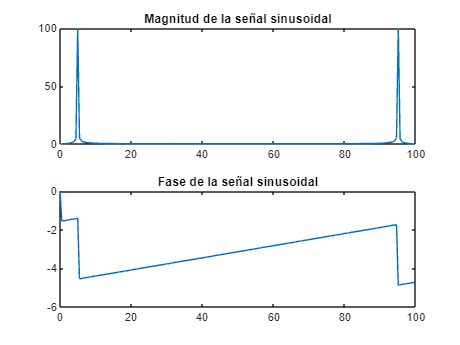


subplot(2,1,1)
plot(frec, M);
title('Magnitud de la señal sinusoidal')
subplot(2,1,2)
plot(frec, P);
title('Fase de la señal sinusoidal')

function [F_dft, M, P, frec] = DTFT(F, T, N, W)
    % Vector de tiempo discreto
    t = (-N:N);
    
    % Evaluar muestras en tiempo discreto
    x = F(t * T);
    
    % Calcular DFT
    Y = fft(x);
    
    % Interpolar la DFT en las frecuencias deseadas (W)
    F_dft = interp1(t, Y, W, 'spline');

    % Calcular la magnitud y fase de la transformada para graficarla
    M = abs(Y); % Magnitud
    Y(M<1e-6) = 0;
    P = unwrap(angle(Y)); % Fase
    frec = (0:length(Y)-1)*100/length(Y);
end